# Reto parte 1

## Parte 1

clear all
clc
% Declaramos constantes globales importantes
% 1000,1e6,100,6000
global M N C m_max
M = 10000; % Dinero total
N = 100;    % Numero de agentes
C = 20;    % Numero de clases
m_max = 800;

## Parte 2

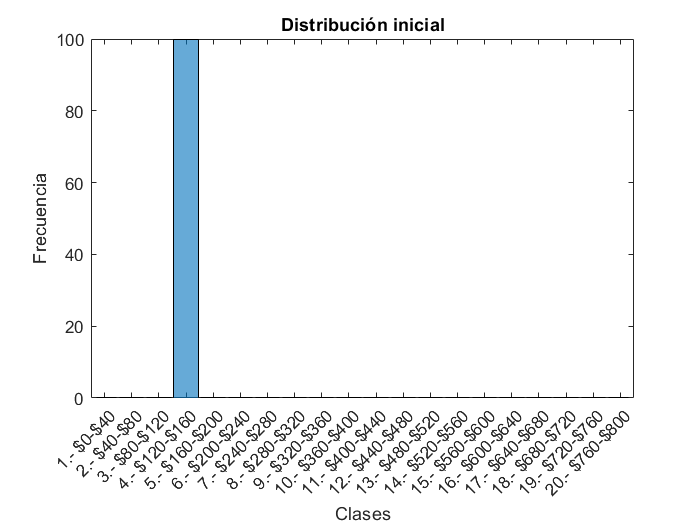

% Tipo de distribucion incial
distribucion_inicial = 1; % Delta = 1, Uniforme = 2
switch distribucion_inicial
    case 1
        % Todos empiezan con la misma cantidad de dinero
        m = M/N; % Dinero recibido por cada agente
        for ii = 1:N
            agentes(ii) = Agente(m); % Creacion de los agentes
        end
    case 2
        % Todas las clases con el mismo numero de personas
        agentes_por_clase = N/C;  %Agentes a alocar a cada clase
        pointer = 0;              %Pointer to shift between money clases 
        for ii = 0:C-1
            m = ii .* m_max/C; %Money in ii'th class.
            for jj = 1+pointer:1:agentes_por_clase+pointer
                agentes(jj) = Agente(m);    %Define Agent
            end
            pointer = pointer + agentes_por_clase;    %Shift pointer
        end
        
        % Normalizar la cantidad de dinero
        dinero_normal= [agentes.dinero]./sum([agentes.dinero]).*M;
        for ii = 1:N
            agentes(ii).dinero = dinero_normal(ii);
        end
end
plotClases(agentes)
title('Distribución inicial')
xlabel('Clases')
ylabel('Frecuencia')

## Parte 3

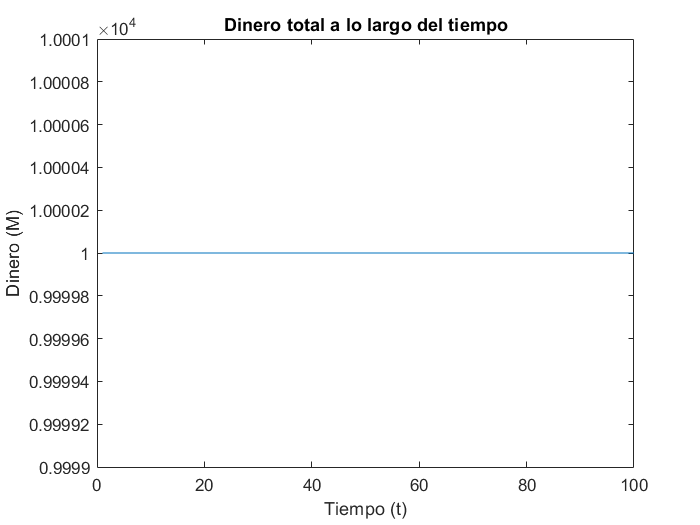

dm = 10; 
n_iteraciones = 100;

[datos_clases,datos_dinero] = simularSistema(agentes,dm,n_iteraciones);
plot(sum(datos_dinero,1))
title('Dinero total a lo largo del tiempo')
xlabel('Tiempo (t)')
ylabel('Dinero (M)')

## Parte 4

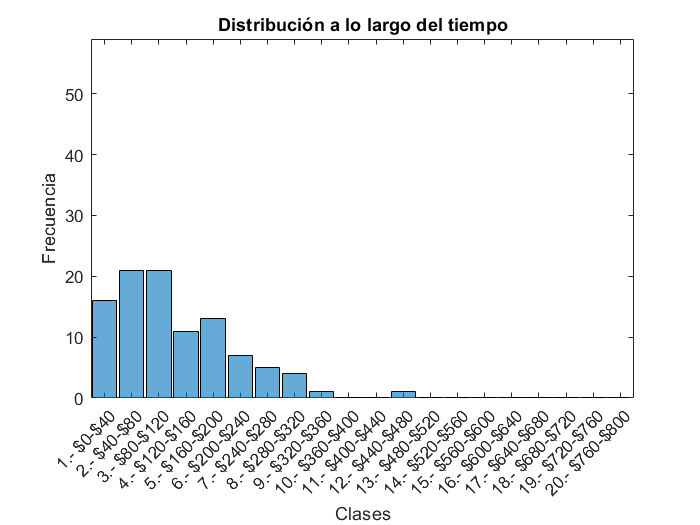

animacionClases(datos_clases)

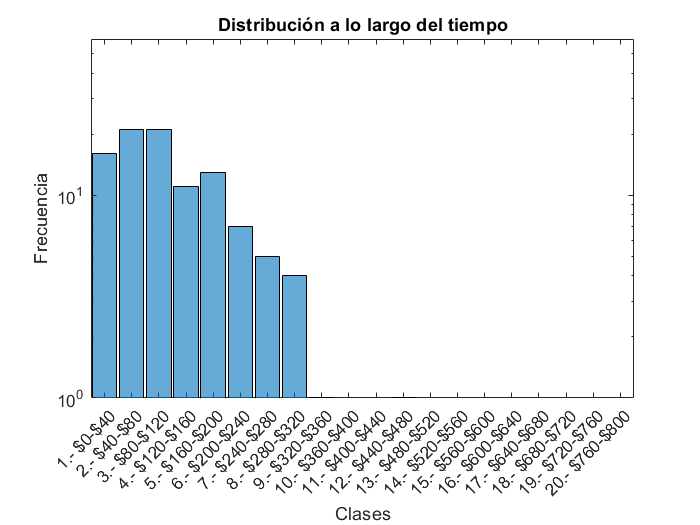

animacionClases(datos_clases,true)

## Parte 5

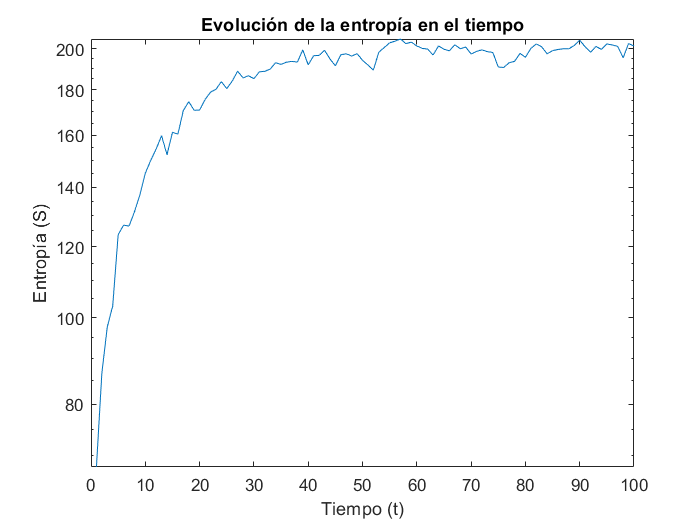

% Calculemos la entropia
plotEntropia(datos_clases,true)

## Parte 7 (con impuestos)

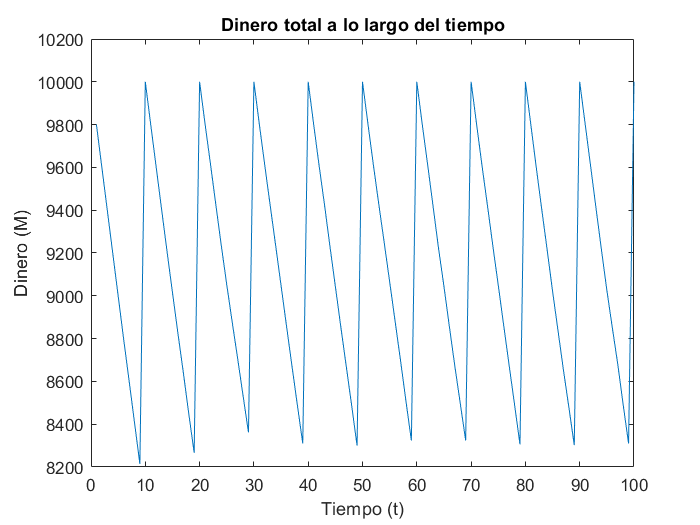

[datos_clases_impuestos,datos_dinero_impuestos] = simularSistema(agentes,dm,n_iteraciones, 0.2, 10);
plot(sum(datos_dinero_impuestos,1))
title('Dinero total a lo largo del tiempo')
xlabel('Tiempo (t)')
ylabel('Dinero (M)')

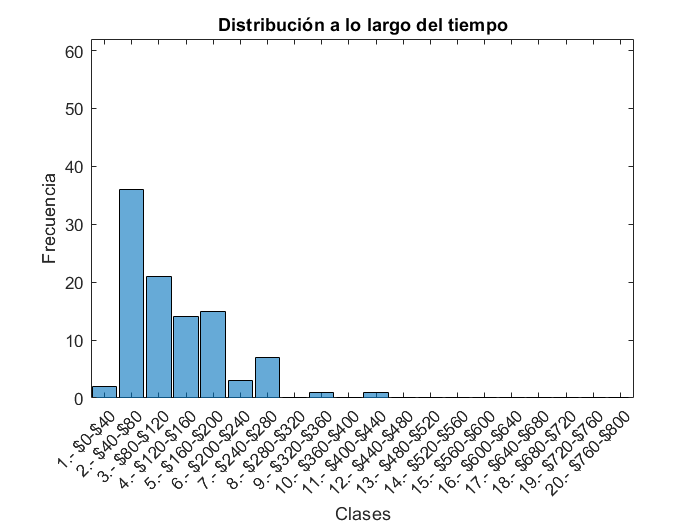

animacionClases(datos_clases_impuestos)

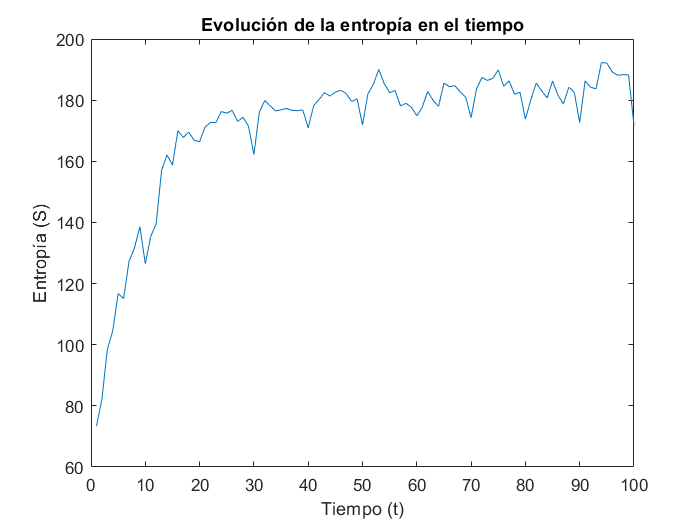

plotEntropia(datos_clases_impuestos)

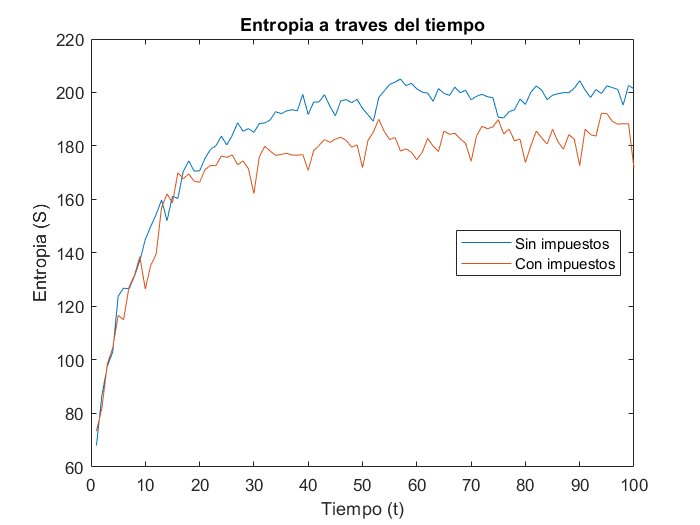

plot(1:n_iteraciones,entropiaTiempo(datos_clases),1:n_iteraciones,entropiaTiempo(datos_clases_impuestos))
legend({'Sin impuestos','Con impuestos'},"Location","east")
title('Entropia a traves del tiempo')
ylabel('Entropia (S)')
xlabel('Tiempo (t)')

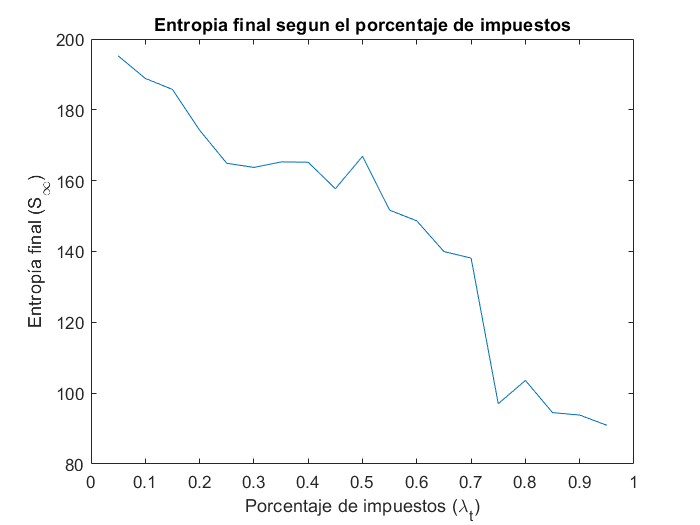

% Comparar distintas lambdas y taus
cc = 1;
S = [];
for ii = 0.05:0.05:0.95
    [datos_clases_var,~] = simularSistema(agentes,dm,n_iteraciones, ii, 10);
    S(cc) = entropiaTiempo(datos_clases_var(:,n_iteraciones));
    cc = cc + 1;
end
plot(0.05:0.05:0.95,S)
title('Entropia final segun el porcentaje de impuestos')
xlabel('Porcentaje de impuestos (\lambda_t)')
ylabel('Entropía final (S_{\infty})')

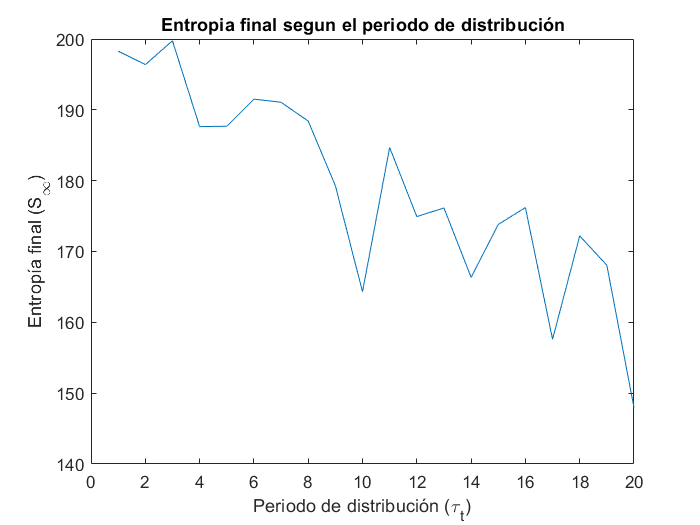

cc = 1;
S = [];
for ii = 1:20
    [datos_clases_var,~] = simularSistema(agentes,dm,n_iteraciones, 0.3, ii);
    S(cc) = entropiaTiempo(datos_clases_var(:,n_iteraciones));
    cc = cc + 1;
end
plot(1:20,S)
title('Entropia final segun el periodo de distribución')
xlabel('Periodo de distribución (\tau_t)')
ylabel('Entropía final (S_{\infty})')

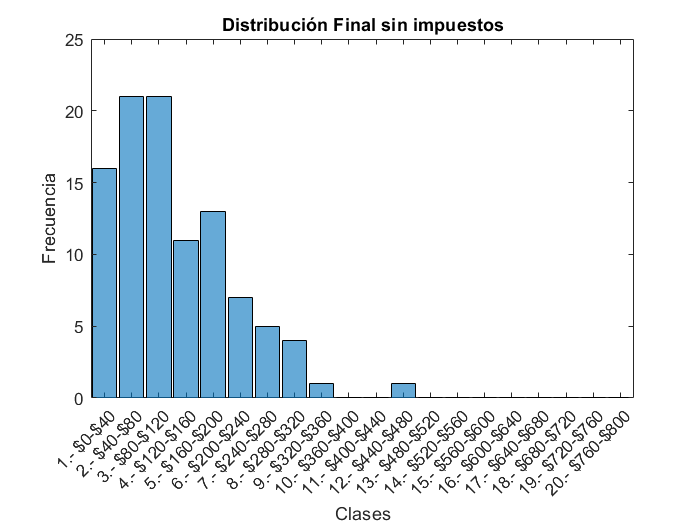

plotClasesFinal(datos_clases(:,n_iteraciones))
title('Distribución Final sin impuestos')
xlabel('Clases')
ylabel('Frecuencia')

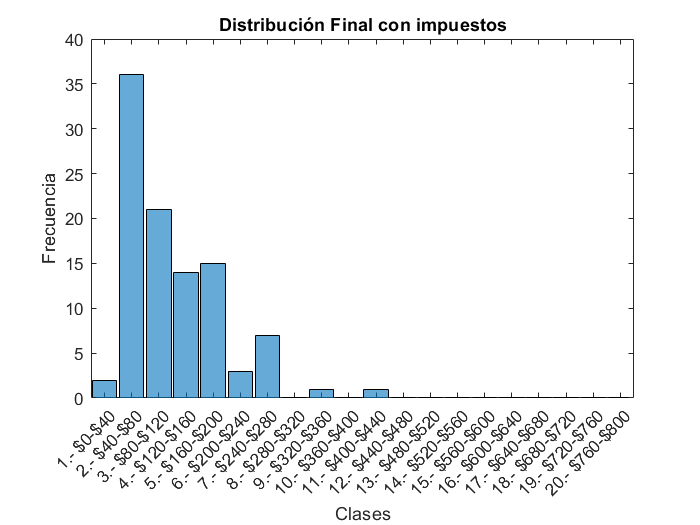

plotClasesFinal(datos_clases_impuestos(:,n_iteraciones))
title('Distribución Final con impuestos')
xlabel('Clases')
ylabel('Frecuencia')

# Reto parte 2

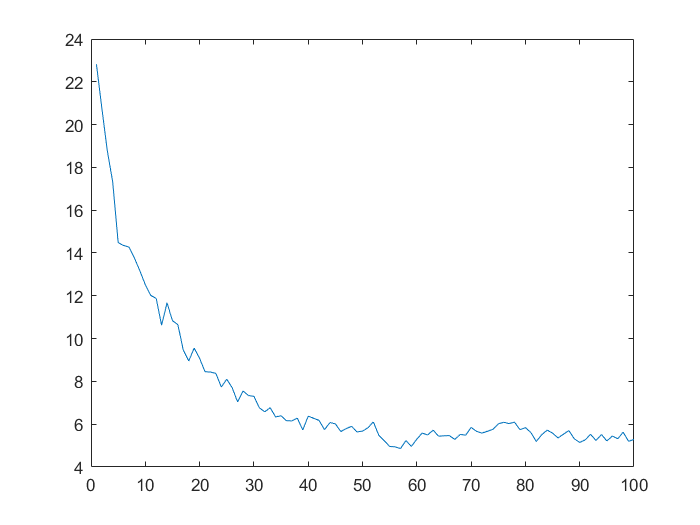

o_t = [];
for tt = 1:n_iteraciones
    o_t(tt) = O(datos_clases(:,tt),datos_dinero(:,tt),'b',0.00005);
end
plot(o_t)